# Dummy maps for cue effect

Model (6cond)

parameter:

- 6 Stimulus onset

- `    cue ``H``igh x stim ``H``igh (onset03_stim)`

- `    cue ``H``igh x stim ``M``ed`

- `    cue ``H``igh x stim ``L``ow`

- `    cue ``L``ow x stim ``H``igh`

- `    cue ``L``ow x stim ``M``ed`

- `    cue ``L``ow x stim ``L``ow`

- `C``ue: onset01_cue`

- `E``xpect rating: onset02_ratingexpect, pmod_expectRT`

- `O``utcome rating: onset04_ratingoutcome, pmod_outcomeRT`

- Motion covariate: 24DOF + CSF

- Spike, as many spikes detected by fmriprep (FD spike threshold 0.9)

# Pain only dummy maps 

# cue effect (high > low)

#### Pain only :: load dataset

clear all;
close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0017.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 19568052 bytes
Loading image number:    49
Elapsed time is 1.556193 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 4766621  Bit rate: 22.18 bits


contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

#### Pain only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              13:45:31 - 10/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


#### Pain only :: Plot diagnostics, before l2norm

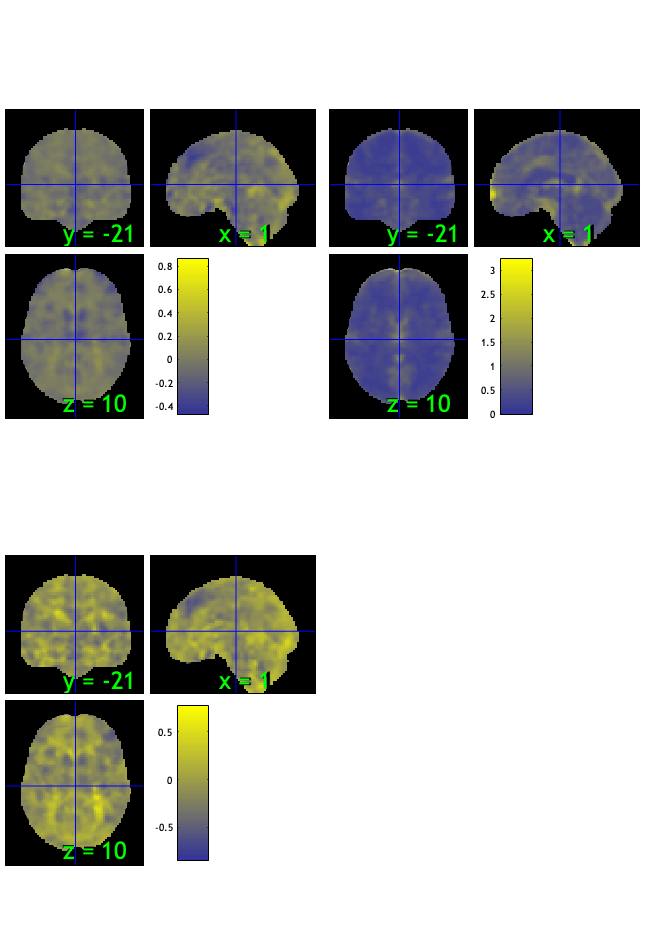

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 24.49%
Expected 2.45 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 1 8 12 
Uncorrected: 3 images		Cases 1 8 12 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 59.18%
Expected 2.45 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               _____________    __________

    global_mean         

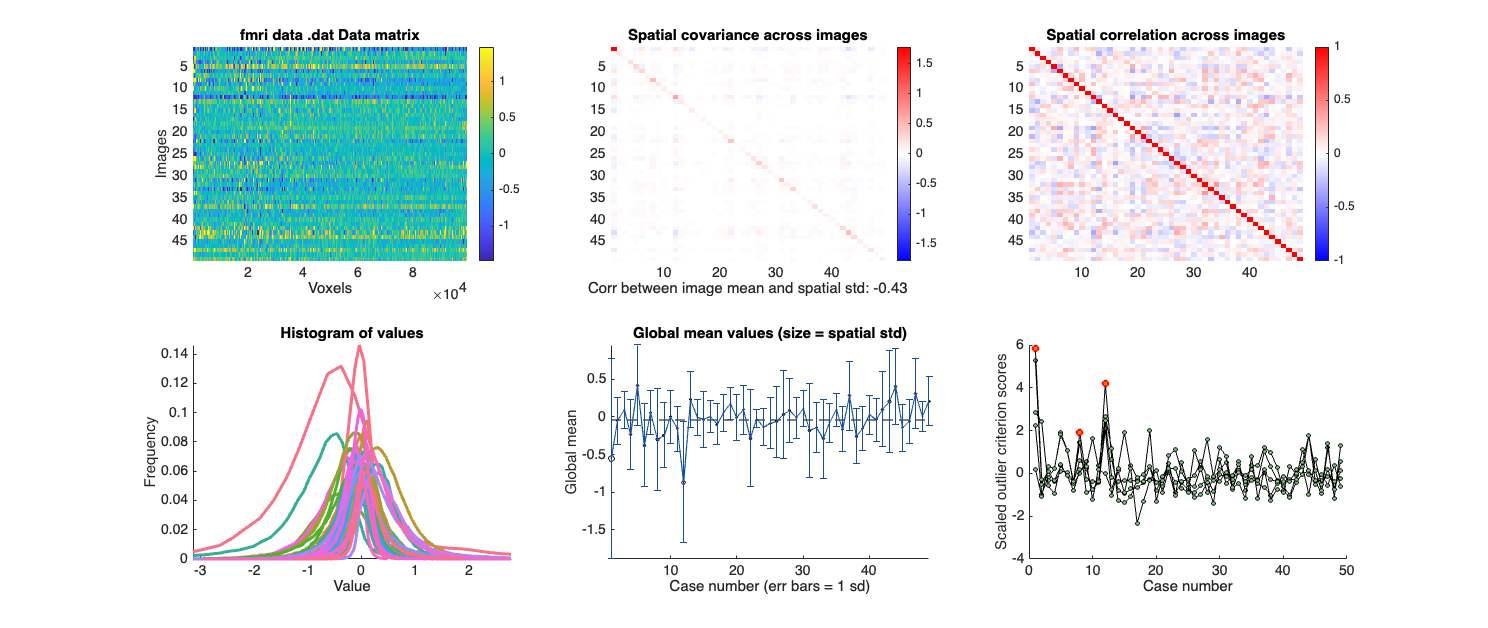

SPM12: spm_check_registration (v7759)              13:45:43 - 10/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
        /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
        /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions
Grouping contiguous voxels:   1 regions
Grouping contiguous voxels:   1 regions


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain only :: run robfit

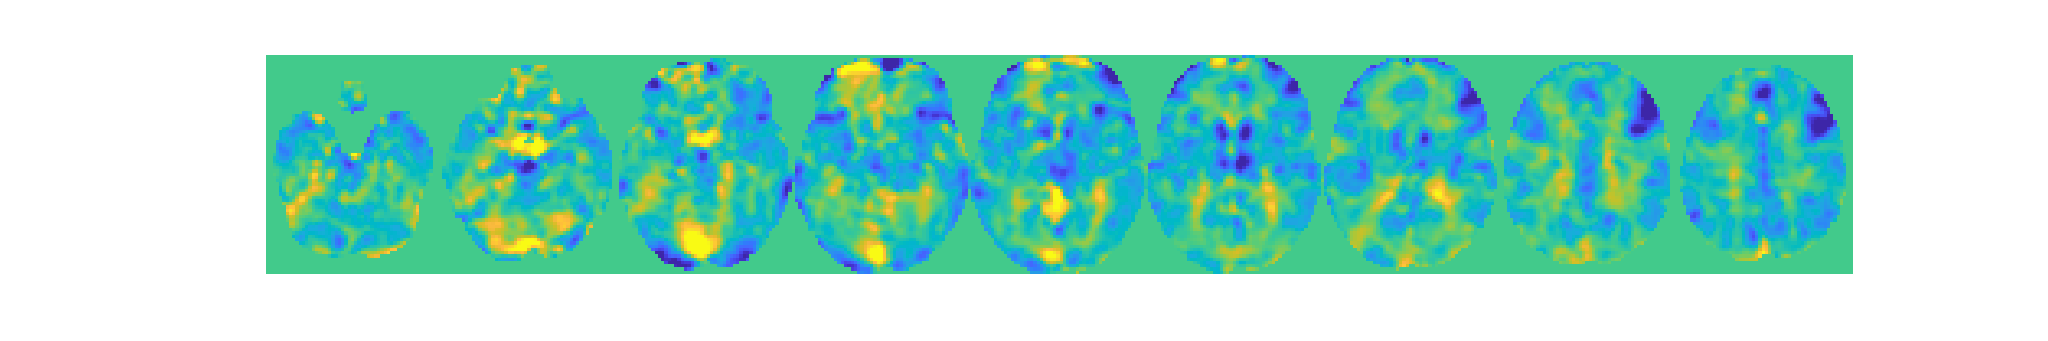

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 49


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 46


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0013"    "participants that are outliers:... sub-0036"    "participants that are outliers:... sub-0044"



disp(n);

    {'sub-0013'}    {'sub-0036'}    {'sub-0044'}



#### Pain only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


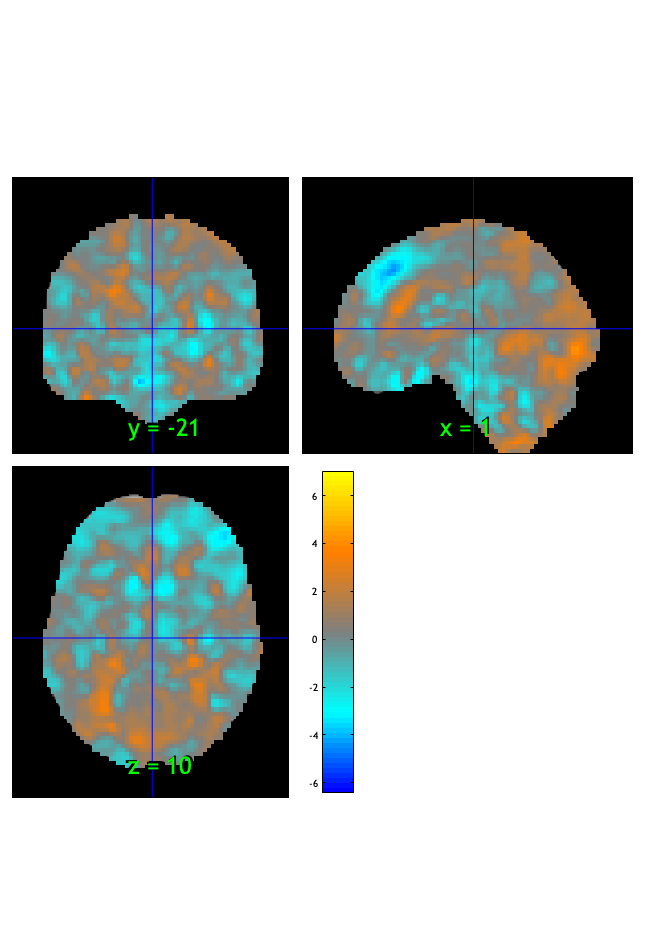

SPM12: spm_check_registration (v7759)              13:45:47 - 10/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

unc_t = threshold(t, .01, 'unc');


Image   1
196 contig. clusters, sizes   1 to 2000
Positive effect: 3610 voxels, min p-value: 0.00000000
Negative effect: 6360 voxels, min p-value: 0.00000012


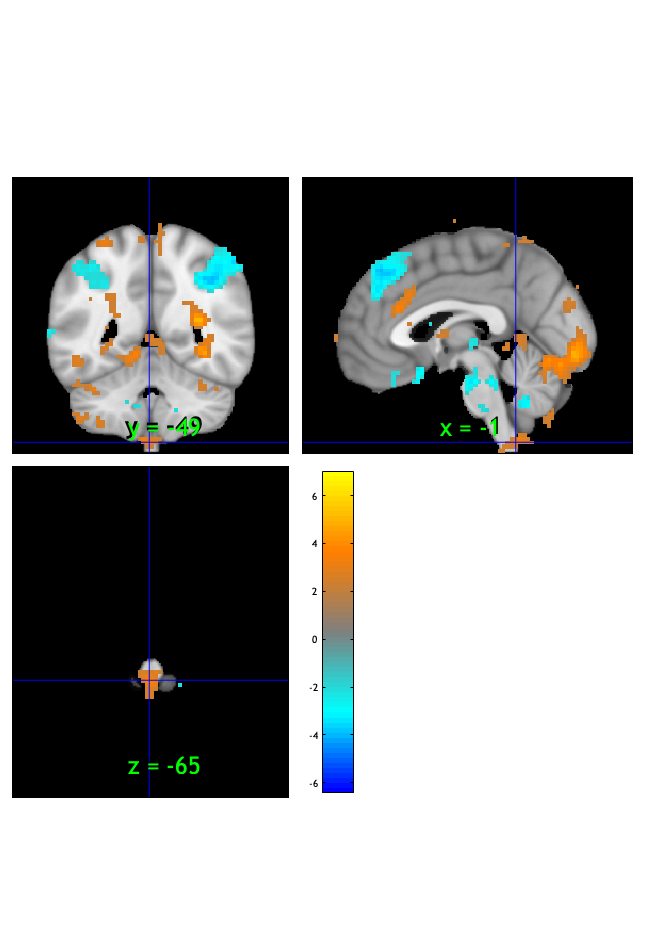

SPM12: spm_check_registration (v7759)              13:45:48 - 10/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(unc_t);

drawnow, snapnow;



fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.000104

Image   1
 11 contig. clusters, sizes   1 to  68
Positive effect:  75 voxels, min p-value: 0.00000000
Negative effect: 137 voxels, min p-value: 0.00000012


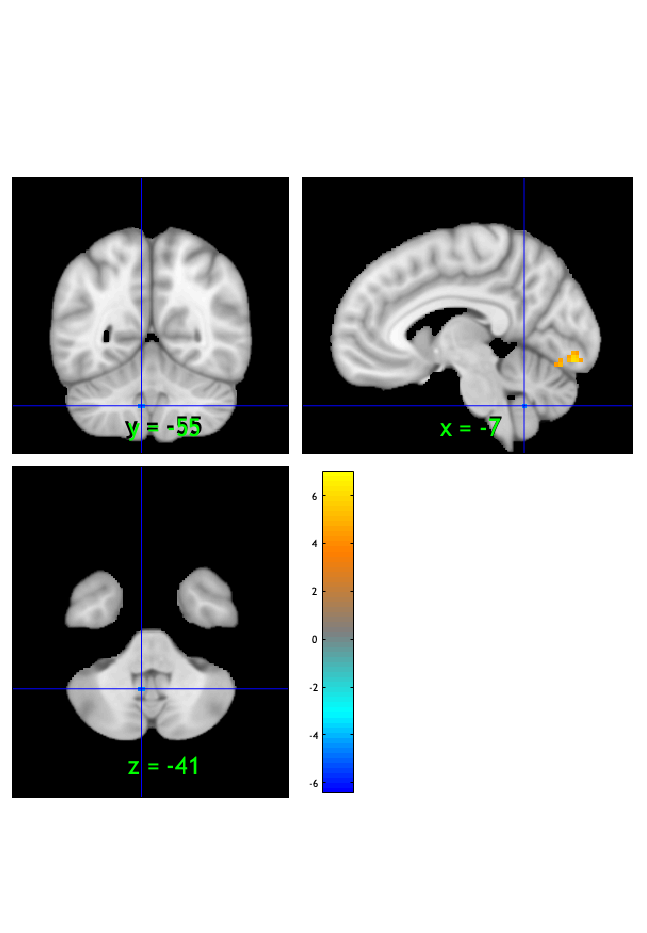

SPM12: spm_check_registration (v7759)              13:45:49 - 10/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000000

Image   1
  0 contig. clusters, sizes     to    
Positive effect:   0 voxels, min p-value: 0.00000000
Negative effect:   0 voxels, min p-value: 0.00000012


SPM12: spm_check_registration (v7759)              13:45:50 - 10/06/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


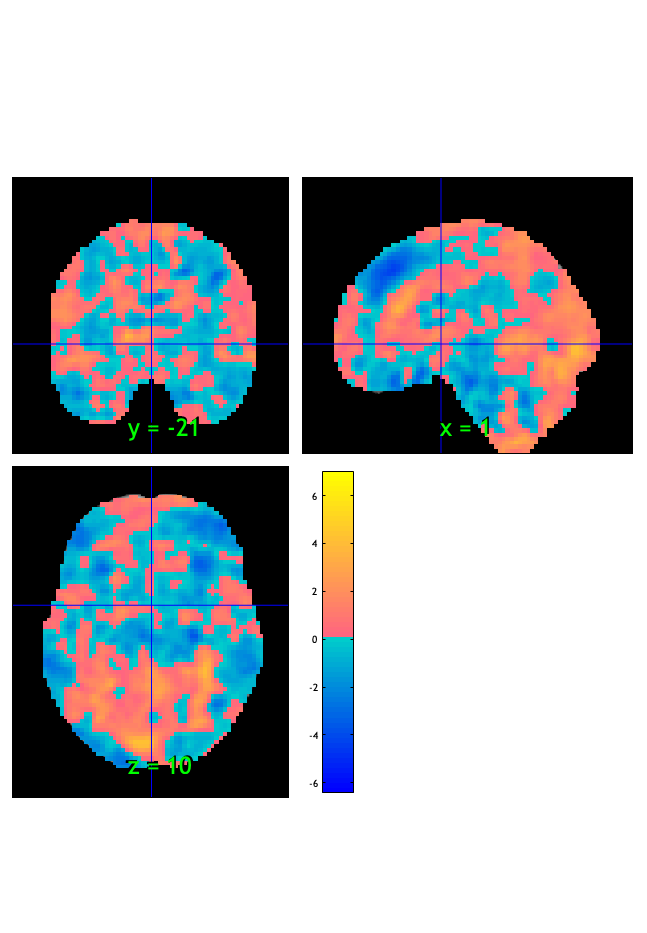

orthviews(fdr_t);

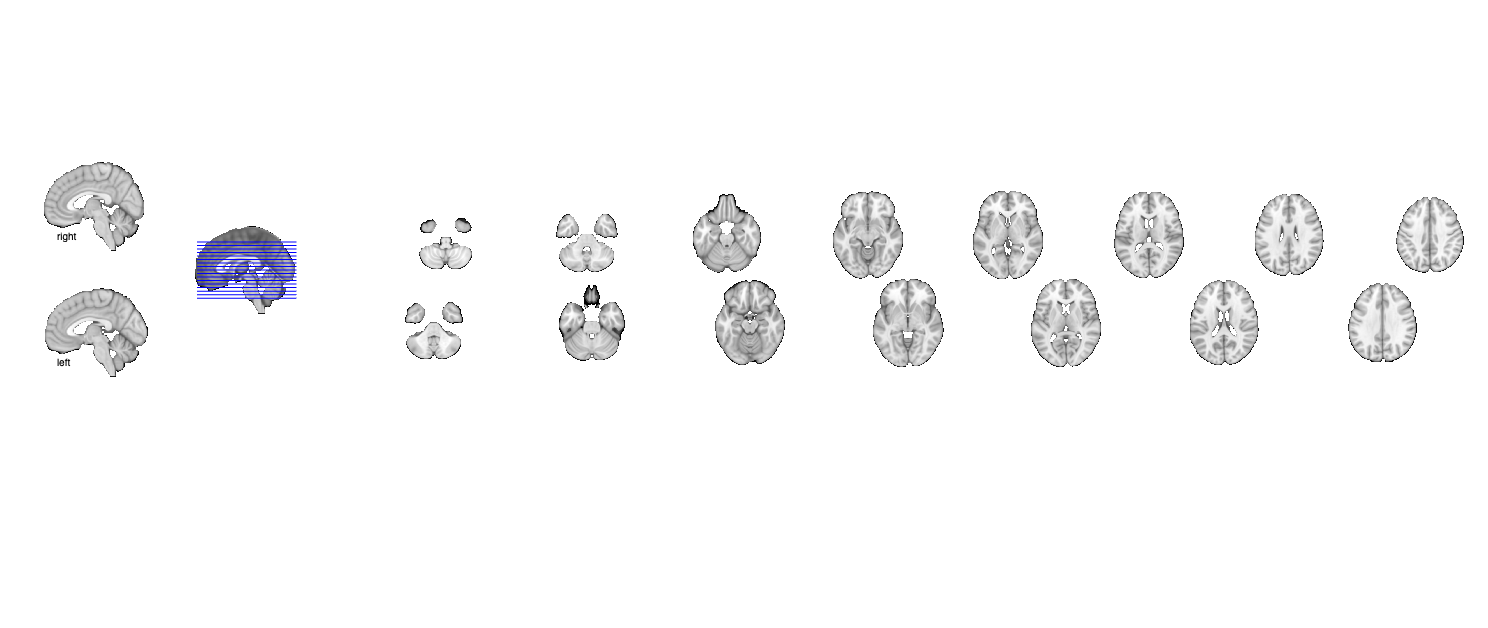

Setting up fmridisplay objects


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

#### Pain only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high     words_high  
    _________    _______________    __________    _____________

    -0.18027     {'correct'    }     0.13376      {'motion'   }
    -0.17754     {'working'    }     0.13066      {'noise'    }
    -0.16497     {'demand'     }     0.11921      {'eye'      }
    -0.15761     {'demands'    }     0.11859      {'frequency'}
    -0.15746     {'executive'  }     0.11826      {'visual'   }
    -0.15586     {'memory'     }     0.11543      {'eyes'     }
    -0.15076     {'control'    }     0.10821      {'images'   }
    -0.14462     {'arithmetic' }     0.10382      {'male'     }
    -0.14423     {'1back'      }     0.10372      {'space'    }
    -0.14004     {'calculation'}     0.10045      {'animal'   }



% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain only :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

CANNOT FIND IMAGES bPLS_pMCC_Pain.nii 


Error using load_image_set>check_image_names_get_full_path
Exiting.

Error in load_image_set>load_kragel18 (line 810)
imagenames = check_image_names_get_full_path(imagenames);

Error in load_image_set (line 358)
            [image_obj, networknames, imagenames] = load_kragel18;

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');
axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious only dummy maps 

# cue effect (high > low)

clear all;
close all;

#### Vicarious only :: load dataset

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0018.nii'));
spm('Defaults','fMRI'); 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

#### Vicarious only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious only :: Plot diagnostics, before l2norm

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious only :: run robfit

set(gcf,'Visible','on');
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));
%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));
[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));
disp(n);

#### Vicarious only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious only :: ttest

t = ttest(imgs2);
orthviews(t);
drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');
orthviews(fdr_t);
drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);
drawnow, snapnow;

#### Vicarious only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Vicarious only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');
bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');
axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive only dummy maps 

# cue effect (high > low)

#### Cognitive only :: load dataset

clear all; close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0019.nii'));
spm('Defaults','fMRI');
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

#### Cognitive only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

#### Cognitive only :: Plot diagnostics, before l2norm

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive only :: run robfit

set(gcf,'Visible','on');
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));
%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));
[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));
disp(n);

#### Cognitive only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive only :: ttest

t = ttest(imgs2);
orthviews(t);
drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');
orthviews(fdr_t);
drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);
drawnow, snapnow;



#### Cognitive only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Cognitive only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');
bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');
axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)
set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')
drawnow, snapnow;

% save html
% pubdir = pwd;
% pubfilename = '6cond_cueeffect_contrast.mlx';
% 
% p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
%   'format', 'html', 'outputDir', pubdir, ...
%   'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
% htmlfile = publish(pubfilename, p);